% Tutorial walking through the process of generating a 3D model from disc annotations. 
% NOTE: Not complete!

% Resources:
% Dunn & Parberry - 3D Math Primer for Graphics and Game Development
% Files on the Matlab File exchange:
% - plot3t, gencyl, matGeom toolbox, quaternion

% Setup some prefs
addpath('C:\Users\sarap\Google Drive\NEITZ Lab\Electron Microscopy Rm\Rendering');

set(0, 'DefaultAxesBox', 'off',...
    'DefaultAxesFontName', 'Roboto',...
    'DefaultAxesLineWidth', 1);

options = optimset('Display', 'final');

% Number of points around the circle
N = 10;
% Vertex points around the circle
angles = 0:(360/N):359.999;

% Make some data
X = [1 1 1 2 2 1 2 3]';
Y = [2 2 1 1 1 1 1 1]';
Z = (1:numel(Y))';
R = [2 2 2 1 1 2 3 4]';
DATA = [X,Y,Z];

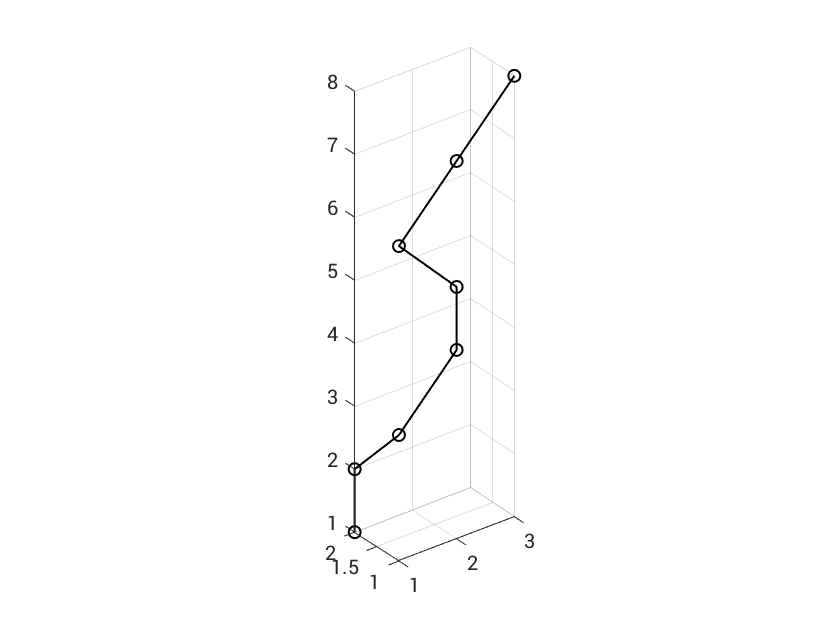

% Display the data:
figure();
plot3(X,Y,Z,'-ok', 'LineWidth', 1);
grid on; view(3); axis tight equal;

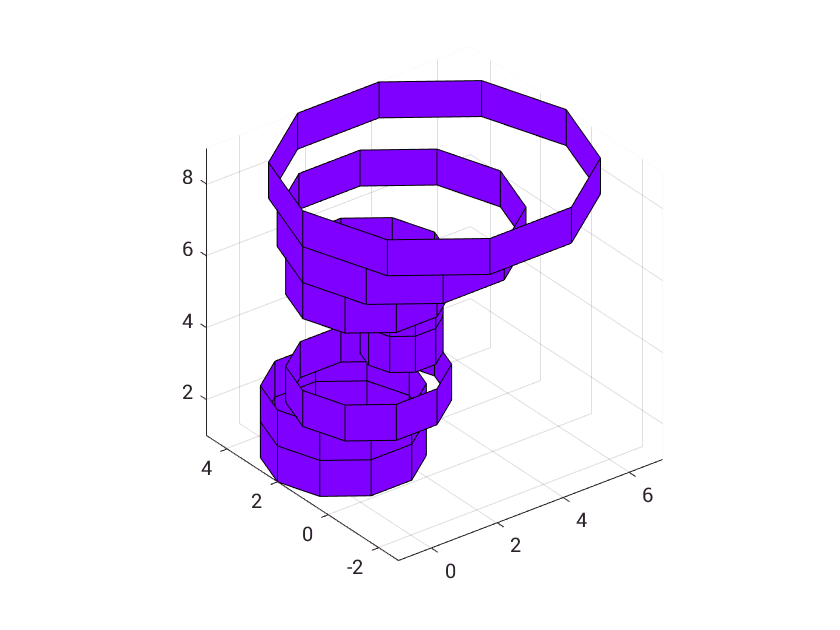

% Using matlab's cylinder
figure(); hold on;
for i = 1:numel(X)
    [x, y, z] = cylinder(R(i), N);
    % Move to the correct X,Y,Z
    surf(...
        'XData', x + X(i),...
        'YData', y + Y(i),...
        'ZData', z + Z(i),...
        'FaceColor', [0.5, 0, 1]);
end
grid on; view(3); axis tight equal;

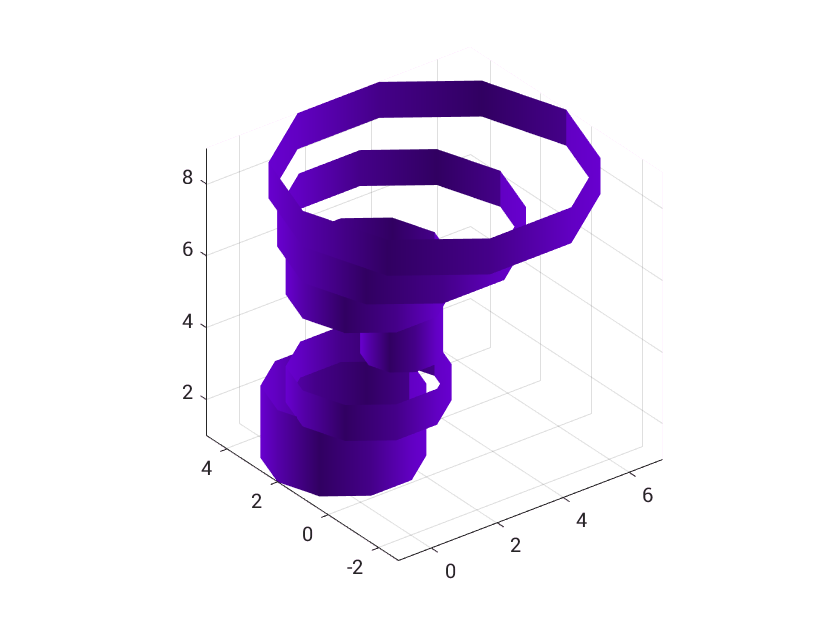

% Quick demo of how to add lighting
lighting gouraud
lightangle(45,30); lightangle(225,30);
set(findall(gca, 'Type', 'surf'), 'EdgeColor', 'none');

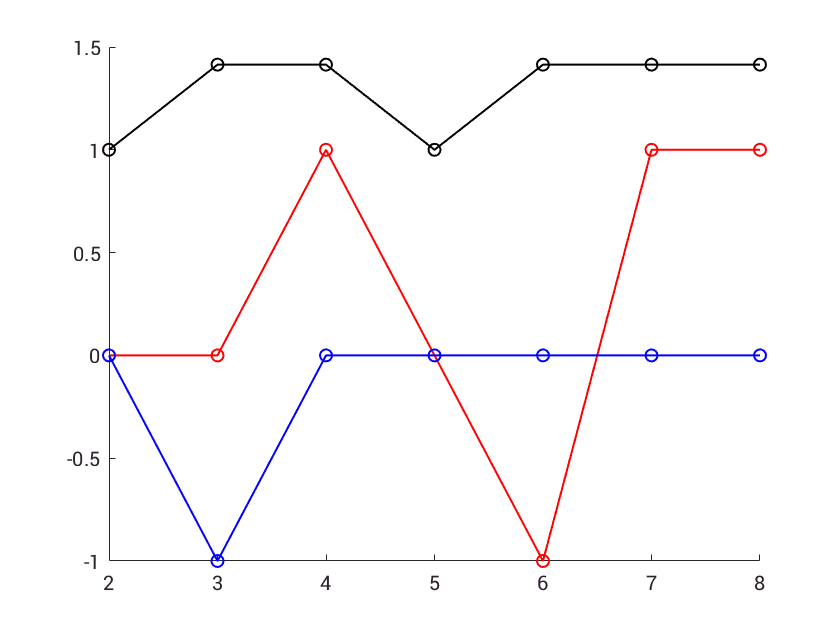

% Difference between each point
D = sqrt((diff(X)).^2 + (diff(Y)).^2 + (diff(Z)).^2);

figure(); hold on;
plot(2:numel(R), D, '-ok', 'LineWidth', 1);
plot(2:numel(R), diff(X), '-or', 'LineWidth', 1);
plot(2:numel(R), diff(Y), '-ob', 'LineWidth', 1);

% Buffer distance between two line pieces
bufferDist = max(R);
            
if (min(D)/2.2) < bufferDist
    bufferDist = min(D)/2.2;
    fprintf('Reset bufferDist to %.2g from %2.g\n',...
    	max(R), bufferDist);
end

Reset bufferDist to 4 from 0.5


% Calculate normals
normal = diff(DATA);

% Keep number of points in line the same
normal = [normal; normal(end,:)];

normal = normal ./ (sqrt(normal(:,1).^2 + normal(:,2).^2 ...
                + normal(:,3).^2) * ones(1,3));

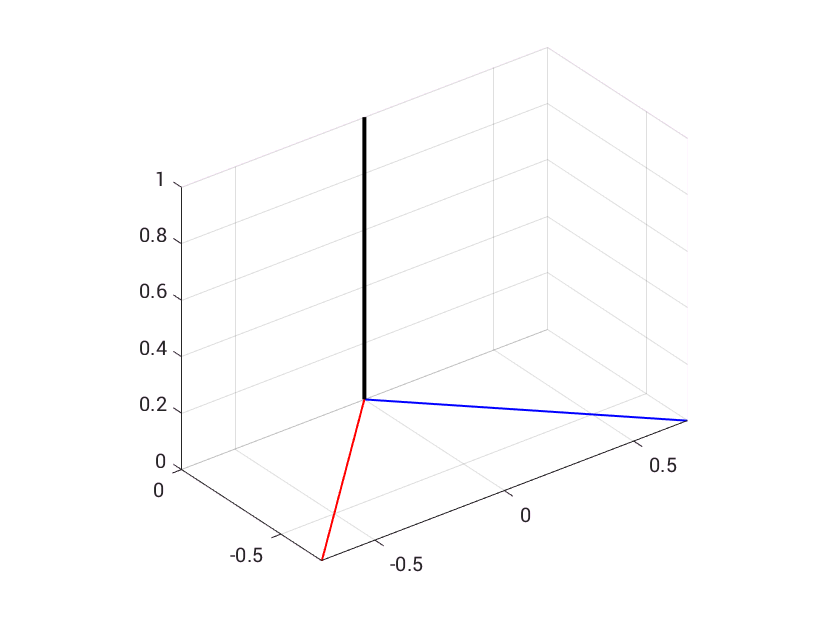

% Get 3D circle coordinates of first circle/cylinder
[a,b] = getab(normal(1,:));

figure(); hold on;
plot3([0 normal(1,1)], [0 normal(1,2)], [0 normal(1,3)],...
    'k', 'LineWidth', 2);
plot3([0 a(1)], [0 a(2)], [0 a(3)], 'r', 'LineWidth', 1);
plot3([0 b(1)], [0 b(2)], [0 b(3)], 'b', 'LineWidth', 1);
grid on; view(3); axis tight equal;

% In plane rotation of 2d circle coordinates
angleOffset = 0;

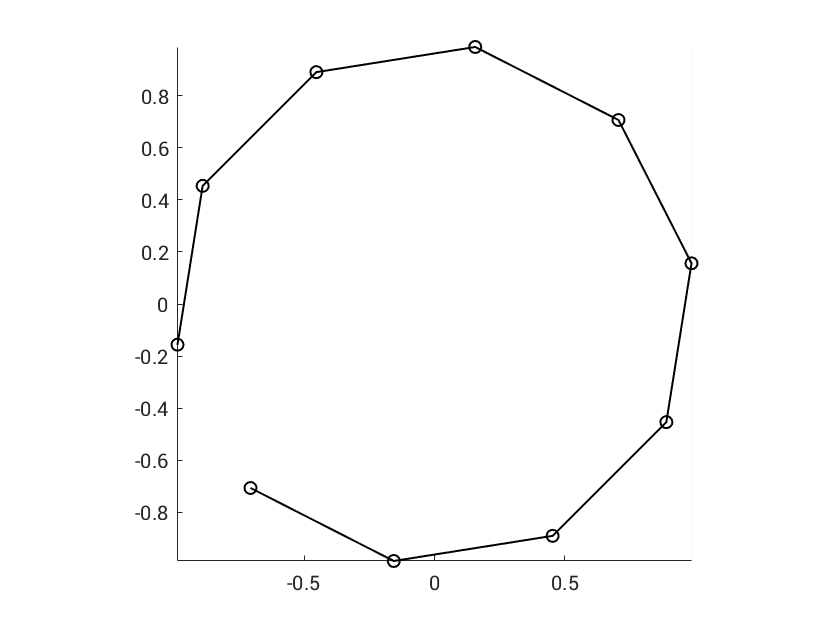

% Just 2D circle coordinates
circum = normalCircle(angles, angleOffset, a, b);

figure(); hold on;
plot(circum(:,1), circum(:,2), '-ok', 'LineWidth', 1);
axis tight equal;

% Track the number of cylinders in region
numCylinders = 0;
% List to store vertex points
FV.vertices = zeros(N * length(DATA), 3);


% Add a half sphere at line start
for j = 5:-0.5:1
    % Translate the circle on it's position on the line
    r = sqrt(1 - (j/5)^2);
    iCirc = r * R(1) * circum + ones(N,1) *...
        (DATA(1,:) - (j/5) * bufferDist * normal(1,:));
    % Create vertex list
    numCylinders = numCylinders + 1;
    FV.vertices(((numCylinders-1)*N+1):(numCylinders*N),:) =...
        [iCirc(:,1), iCirc(:,2), iCirc(:,3)];
end

j = 5 - Setting 1-10
j = 4.5 - Setting 11-20
j = 4 - Setting 21-30
j = 3.5 - Setting 31-40
j = 3 - Setting 41-50
j = 2.5 - Setting 51-60
j = 2 - Setting 61-70
j = 1.5 - Setting 71-80
j = 1 - Setting 81-90


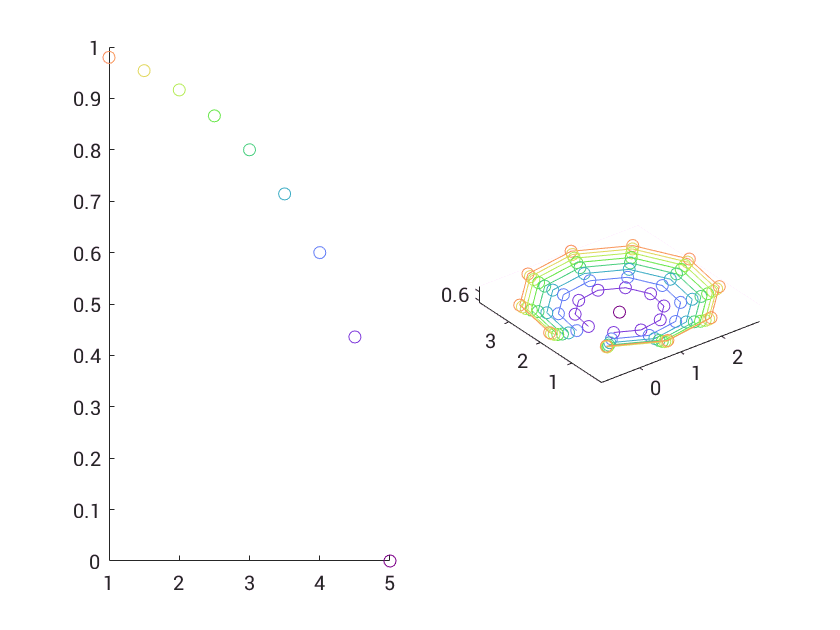

% This repeats the previous block and displays output
figure(); hold on;
ax1 = subplot(121); hold on;
ax2 = subplot(122); hold on;
co = pmkmp(numel(5:-0.5:1), 'cubicl');
numColor = 0;

all_r = [];
for j = 5:-0.5:1
    numColor = numColor + 1;
    r = sqrt(1 - (j/5)^2);
    plot(ax1, j, r, 'o', 'Color', co(numColor,:));
    iCirc = r * R(1) * circum + ones(N,1) *...
        (DATA(1,:) - (j/5) * bufferDist * normal(1,:));
    plot3(ax2, iCirc(:,1), iCirc(:,2), iCirc(:,3),...
        '-o', 'Color', co(numColor,:));
end
view(ax2, 3); axis equal

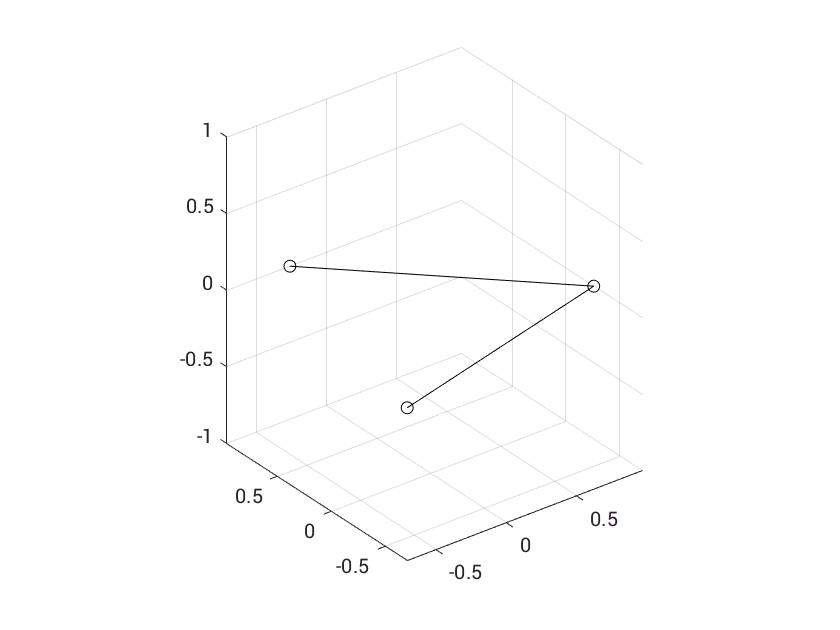

% Make a 3 point circle to be rotated
% and aligned with the next circle
circmo = normalCircle([0 120 240], 0, a, b);

figure(); hold on;
plot3(circmo(:,1), circmo(:,2), circmo(:,3), '-ok');
view(3); axis equal; grid on;

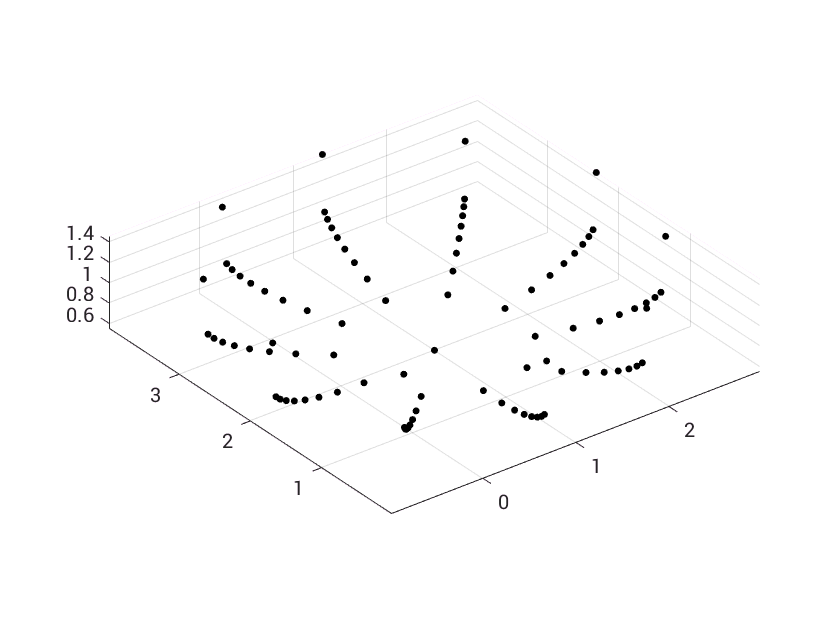

% This plot will track the progress of vertices
ax = axes('Parent', figure); hold on;
plot3(ax, FV.vertices(:,1), FV.vertices(:,2), FV.vertices(:,3),...
    '.k', 'MarkerSize', 12);
view(ax, 3); axis tight equal; grid on;

Wrapped in a for loop:

i = 1; % Line Segment
% Current data point
iNormal = normal(i,:); 
iData = DATA(i,:);
% Next data point
jNormal = normal(i+1,:);
jData = DATA(i+1,:);


Step One: Create a main cylinder between two line points.

This is just 2 connected line points, current point and the next

% Calculate the 3D circle coordinates
[a, b] = getab(iNormal);
circm = normalCircle(angles, angleOffset, a, b);
% This is the same as the last output of normalCircle

% There are two steps here
% First circm is scaled by the radius to be appropriately sized
% Next, it is translated by the data points
circmp = circm*R(i)...
    + ones(N,1)*(iData+bufferDist*iNormal);
numCylinders = numCylinders + 1;
FV.vertices(((numCylinders-1)*N+1):(numCylinders*N),:) =...
    [circmp(:,1), circmp(:,2), circmp(:,3)];

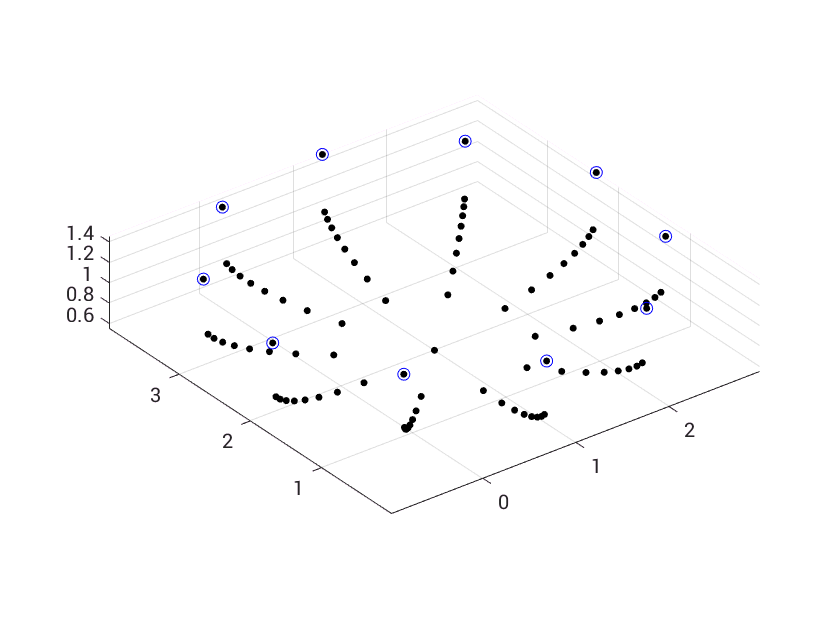

% Add to existing plot
plot3(ax, circmp(:,1), circmp(:,2), circmp(:,3), 'ob');

% Repeat the steps above
% But here it's working back from the next data points
circmp = circm * R(i+1) + ...
    ones(N,1) * (jData - bufferDist*iNormal);
numCylinders = numCylinders + 1;
FV.vertices(((numCylinders-1)*N+1):(numCylinders*N),:) =...
    [circmp(:,1), circmp(:,2), circmp(:,3)];

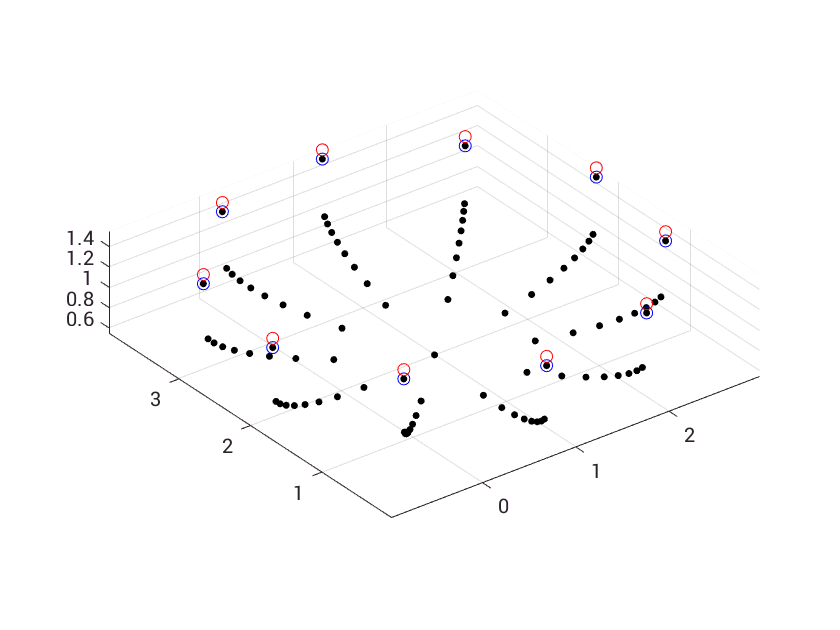

% Add to existing plot
plot3(ax, circmp(:,1), circmp(:,2), circmp(:,3), 'or');

% Create an in between cicle to smoothly connect the lines
ijNormal = iNormal + jNormal;
ijNormal = ijNormal ./ sqrt(sum(ijNormal.^2));
ijData = 0.5858* jData...
    + 0.4142*(0.5*((jData + bufferDist*jNormal)...
    + (jData - bufferDist*iNormal)));

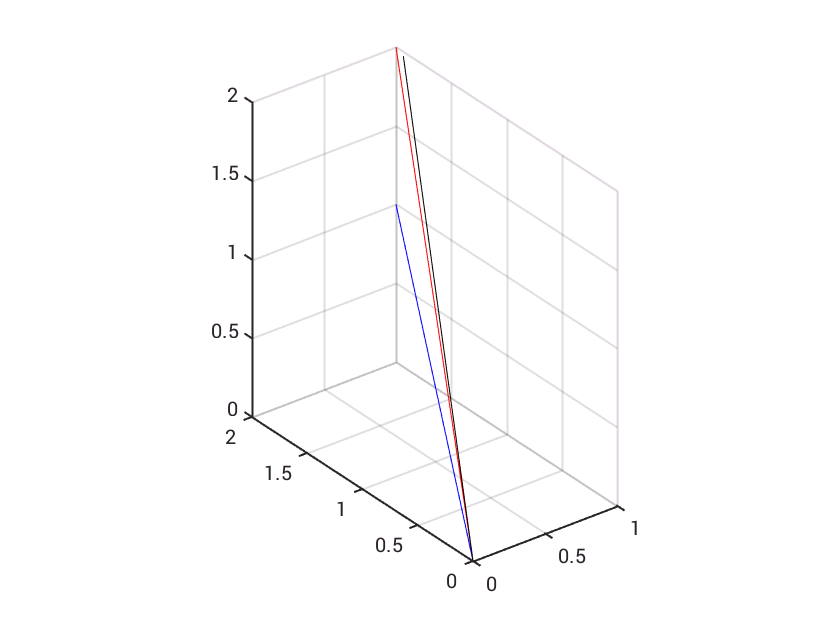

% Display the normals (Not particularly helpful)
figure(); hold on;
plot3([0 iData(1)], [0 iData(2)], [0 iData(3)], 'b');
plot3([0 jData(1)], [0 jData(2)], [0 jData(3)], 'r');
plot3([0 ijData(1)], [0 ijData(2)], [0 ijData(3)], 'k');
view(3); axis equal; grid on;

% Rotate the circle coordinates in plane to align with the 
% previous circle by minimizing the distance between the
% coordinates of the two circles (each with 3 coordinates).
[a, b] = getab(ijNormal);


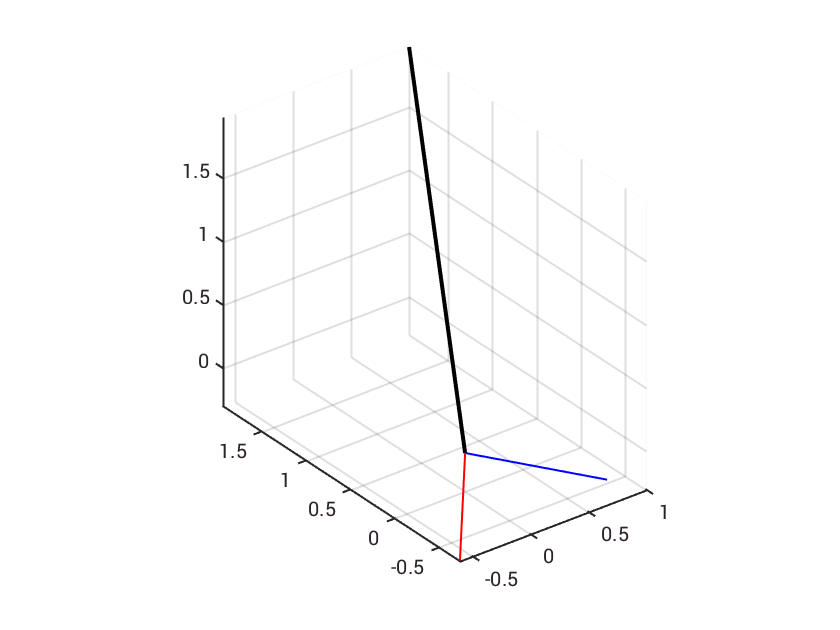

% Display as well
figure(); hold on;
plot3([0 a(1)], [0 a(2)], [0 a(3)], 'r', 'LineWidth', 1);
plot3([0 b(1)], [0 b(2)], [0 b(3)], 'b', 'LineWidth', 1);
plot3([0 ijData(1)], [0 ijData(2)], [0 ijData(3)],...
    'k', 'LineWidth', 2);
view(3); axis equal; grid on;

% Actual minimization referenced above
[angleOffset, ~, exitFlag] = fminsearch(...
    @(j) minimizeRot([0 120 240], circmo, 1, a, b),...
    angleOffset, options);

 
Optimization terminated:
 the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-04 
 and F(X) satisfies the convergence criteria using OPTIONS.TolFun of 1.000000e-04 



% Not very exiting... the angle offset was already good
fprintf('Angle offset = %.2g\n', angleOffset);

Angle offset = 0


% If the exit flag shows a failure to converge,
% we switch algorithms.. this doesn't happen too often
fprintf('Exit flag = %u\n', exitFlag);

Exit flag = 1


% Keep a 3 point circle for rotation alignment with the
% next circle. Redundant now but will be important when
% minimizeRot does find a different angle offset
[a, b] = getab(ijNormal);
circmo = normalCircle([0 120 240], angleOffset, a, b);


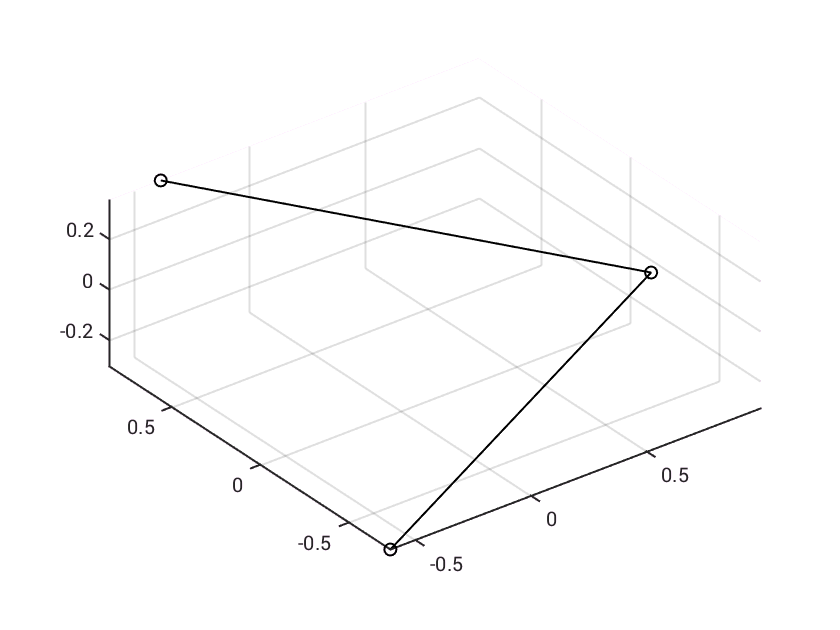

figure(); hold on;
plot3(circmo(:,1), circmo(:,2), circmo(:,3),...
    '-ok', 'LineWidth', 1);
    view(3); grid on; axis equal;

% Calculate the 3D circle coordinates
circm = normalCircle(angles, angleOffset, a, b);
circmp = circm*R(i+1) + ones(N,1)*(ijData);


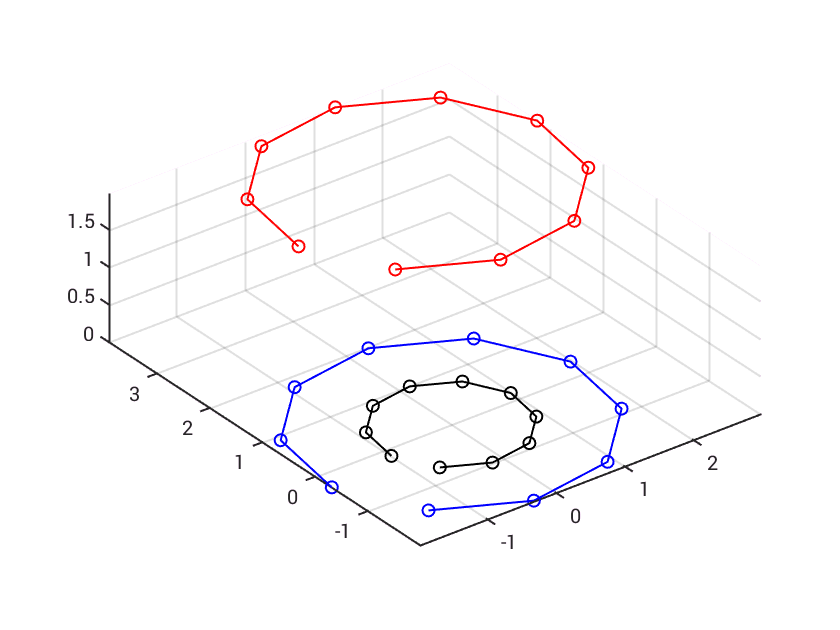

% Breaking down the last two lines:
figure(); hold on;
% Unit circle (2D) located at Z = 0
plot3(circm(:,1), circm(:,2), circm(:,3), '-ok', 'LineWidth', 1);
view(3); axis equal tight; grid on
% Scaled
tmp = circm*R(i+1);
plot3(tmp(:,1), tmp(:,2), tmp(:,3), '-ob', 'LineWidth', 1);
% Translated
tmp = tmp + ones(N,1)*(ijData);
plot3(tmp(:,1), tmp(:,2), tmp(:,3), '-or', 'LineWidth', 1);